# Plot M3C Variables

% save('TestBench\Data\bufferNN.mat', 'buffer')

buffer =   ClassBuffer with properties:

                 Ts: 1.6667e-04
                 Ns: 6000
                  m: 6
                  n: 2
                  A: [5×6 double]
                  p: 2
                  q: 3
               Tsim: [0 1.6669e-04 3.3339e-04 5.0008e-04 6.6678e-04 8.3347e-04 0.0010 0.0012 0.0013 0.0015 0.0017 0.0018 0.0020 0.0022 0.0023 0.0025 0.0027 0.0028 0.0030 0.0032 0.0033 0.0035 0.0037 0.0038 0.0040 0.0042 0.0043 0.0045 … ] (1×6000 double)
                 is: [6×6000 double]
                ixy: [5×6000 double]
                 iB: [6×6000 double]
                 iz: [6×6000 double]
                 ie: [2×6000 double]
                 vs: [6×6000 double]
                vxy: [5×6000 double]
                 vB: [6×6000 double]
                 vo: [-1.9415e-29 4.6974e-05 2.0637e-04 4.6543e-04 7.8927e-04 0.0011 0.0014 0.0016 0.0015 0.0011 4.0521e-04 -7.4465e-04 -0.0024 -0.0044 -0.

Tsim = buffer.Tsim;
clf

% name = 'summaryBCD';
% X = Tsim';
% X = [X, buffer.wy'];
% X = [X, buffer.ixy'];
% X = [X, buffer.ixy_ref'];
% X = [X, buffer.vc'];
% X = [X, buffer.ie'];
% X = [X, buffer.ie_ref'];
% X = [X, buffer.vo'];
% 
% [Nsamples, Nvars] = size(X);
% signalNames = {'Time', ...
%                'wy', ...
%                'iu', 'il', 'ia', 'ib', 'ic', ...
%                'iu_ref', 'il_ref', 'ia_ref', 'ib_ref', 'ic_ref', ...
%                'vc_ua', 'vc_ub', 'vc_uc', ...
%                'vc_la', 'vc_lb', 'vc_lc', ...
%                'ie1', 'ie2', ...
%                'ie1_ref', 'ie2_ref', ...
%                'vo'};
% T = array2table(X, 'VariableNames', signalNames);
% writetable(T, strcat(['TestBench\Data\', name,'.csv']));

## `vxy`

% abc

figure
subplot(2, 1, 1)
hold on
stairs(Tsim, buffer.vxy(1:buffer.p, :)')
hold off
legend('vxa', 'vxb', 'vxc')

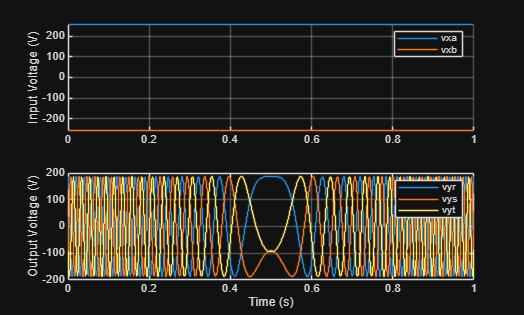

ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(Tsim, buffer.vxy(buffer.p+1:end, :)')
legend('vyr', 'vys', 'vyt')
ylabel('Output Voltage (V)')
grid on
xlabel('Time (s)')

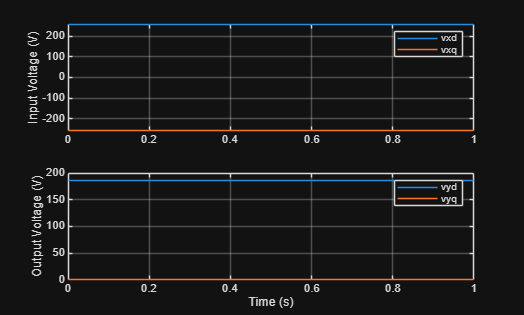


% dq

figure
subplot(2, 1, 1)
stairs(Tsim, buffer.vxdq')
legend('vxd', 'vxq')
ylabel('Input Voltage (V)')
grid on

subplot(2, 1, 2)
stairs(Tsim, buffer.vydq')
legend('vyd', 'vyq')
ylabel('Output Voltage (V)')
grid on

xlabel('Time (s)')

## Input PLL

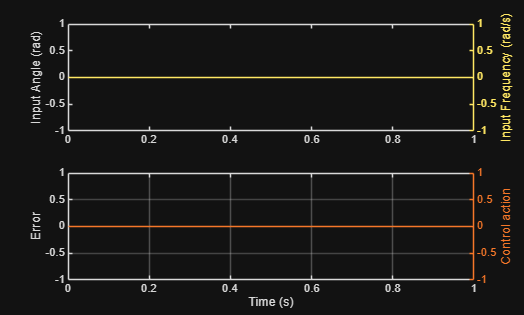

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(Tsim, buffer.gx')
hold on
stairs(Tsim, buffer.gx_pll', '--')
hold off
ylabel('Input Angle (rad)')

% Frequency
yyaxis right
stairs(Tsim, buffer.wx')
hold on
stairs(Tsim, buffer.wx_pll', '--')
hold off
ylabel('Input Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(Tsim, buffer.ex_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(Tsim, buffer.ux_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## Output PLL

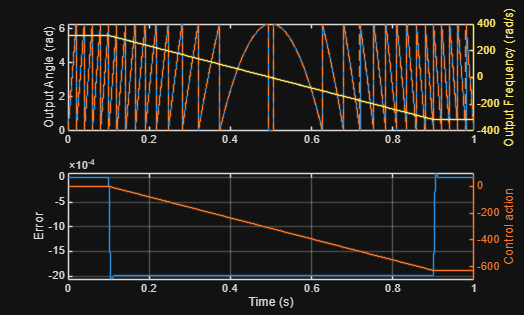

figure

% Estimations
subplot(2, 1, 1)

% Angle
stairs(Tsim, buffer.gy')
hold on
stairs(Tsim, buffer.gy_pll', '--')
hold off
ylabel('Output Angle (rad)')

% Frequency
yyaxis right
stairs(Tsim, buffer.wy')
hold on
stairs(Tsim, buffer.wy_pll', '--')
hold off
ylabel('Output Frequency (rad/s)')

% Performance
subplot(2, 1, 2)

% Error
stairs(Tsim, buffer.ey_pll')
ylabel('Error')

% Control action
yyaxis right
stairs(Tsim, buffer.uy_pll')
ylabel('Control action')

xlabel('Time (s)')
grid on

## `vB`

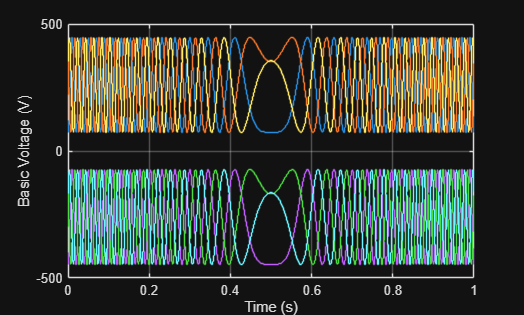

figure
stairs(Tsim, buffer.vB')
xlabel('Time (s)')
ylabel('Basic Voltage (V)')
grid on

## `vs`

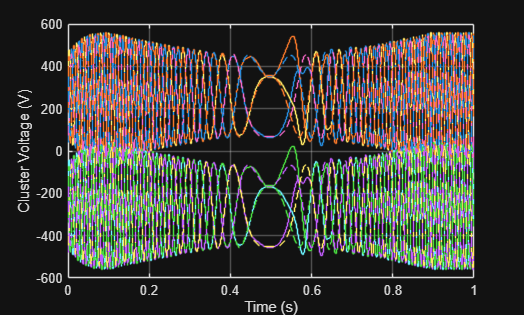

figure
stairs(Tsim, buffer.vs')
hold on
stairs(Tsim, buffer.vs_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')
grid on

## is

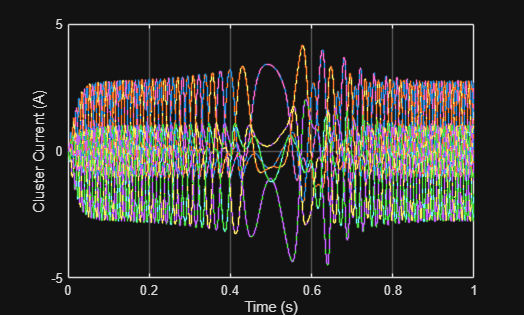

figure
stairs(Tsim, buffer.is')
hold on
stairs(Tsim, buffer.is_ref', '--')
hold off
xlabel('Time (s)')
ylabel('Cluster Current (A)')
grid on

## ixy

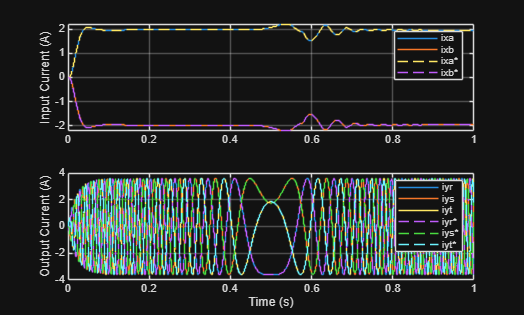

% abc

figure
subplot(2, 1, 1)
stairs(Tsim, buffer.ixy(1:buffer.p, :)')
hold on
stairs(Tsim, buffer.ixy_ref(1:buffer.p, :)', '--')
hold off
if and(buffer.p == 3, buffer.q == 3)
    legend('ixa', 'ixb', 'ixc', 'ixa*', 'ixb*', 'ixc*')
elseif and(buffer.p == 2, buffer.q == 3)
    legend('ixa', 'ixb', 'ixa*', 'ixb*')
end
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(Tsim, buffer.ixy(buffer.p+1:end, :)')
hold on
stairs(Tsim, buffer.ixy_ref(buffer.p+1:end, :)', '--')
hold off
legend('iyr', 'iys', 'iyt', 'iyr*', 'iys*', 'iyt*')
ylabel('Output Current (A)')
grid on
xlabel('Time (s)')

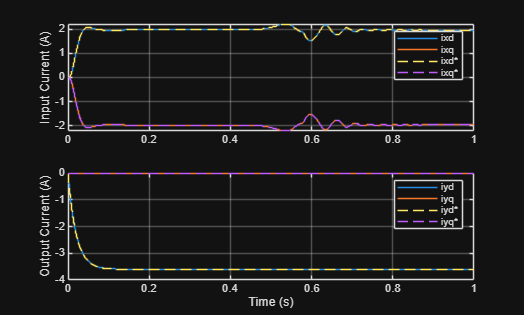


% dq

figure
subplot(2, 1, 1)
stairs(Tsim, buffer.ixdq')
hold on
stairs(Tsim, buffer.ixdq_ref', '--')
hold off
legend('ixd', 'ixq', 'ixd*', 'ixq*')
ylabel('Input Current (A)')
grid on

subplot(2, 1, 2)
stairs(Tsim, buffer.iydq')
hold on
stairs(Tsim, buffer.iydq_ref', '--')
hold off
legend('iyd', 'iyq', 'iyd*', 'iyq*')
ylabel('Output Current (A)')
grid on

xlabel('Time (s)')

## `iB`

% figure
% stairs(Tsim, buffer.iB')
% hold on
% stairs(Tsim, buffer.iB_ref', '--')
% hold off
% xlabel('Time (s)')
% ylabel('Basic Current (A)')
% grid on

## `iz`

% figure
% stairs(Tsim, buffer.iz')
% hold on
% stairs(Tsim, buffer.iz_ref', '--')
% hold off
% xlabel('Time (s)')
% ylabel('Circulating Current (A)')
% grid on

## `Ec`

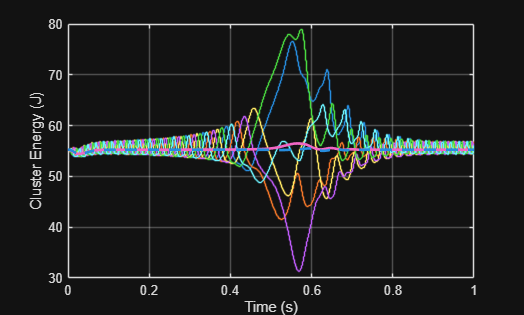

figure
stairs(Tsim, buffer.Ec')
hold on
stairs(Tsim, buffer.Ec_mean', 'LineWidth', 2)
stairs(Tsim, buffer.Ec_mean_filt', '--', 'LineWidth', 2)
hold off
ylabel('Cluster Energy (J)')
xlabel('Time (s)')
grid on

## TEB PI

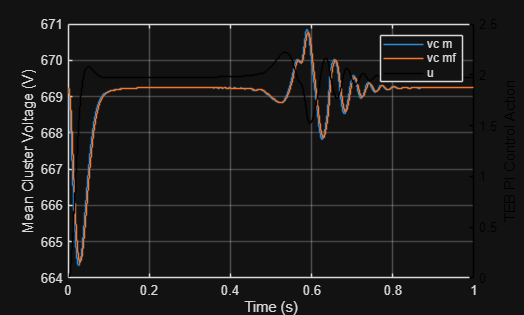

figure

stairs(Tsim, buffer.vc_mean')
hold on
stairs(Tsim, buffer.vc_mean_filt')
hold off
ylabel('Mean Cluster Voltage (V)')

yyaxis right
stairs(Tsim, buffer.u_TEB', 'Color', 'black')
ylabel('TEB PI Control Action')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

legend('vc m', 'vc mf', 'u')
xlabel('Time (s)')
grid on

## `vc`

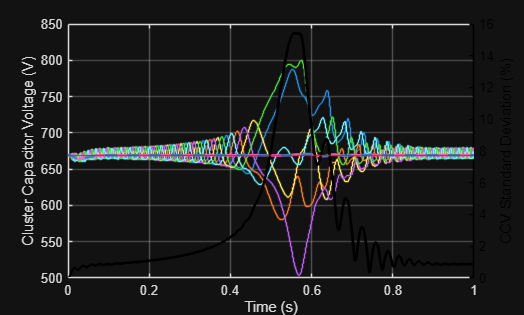

figure

stairs(Tsim, buffer.vc')
hold on
stairs(Tsim, buffer.vc_mean', 'LineWidth', 2)
stairs(Tsim, buffer.vc_mean_filt', '--', 'LineWidth', 2)
yline(buffer.vc_mean(1), 'Color', 'red')
hold off
ylabel('Cluster Capacitor Voltage (V)')

yyaxis right
stairs(Tsim, 100*std(buffer.vc./buffer.vc_mean)', 'LineWidth', 2, 'Color', 'black')
ylabel('CCV Standard Deviation (%)')
ax = gca;
ax.YAxis(2).Color = 'black';
ax.YColor = 'black';

xlabel('Time (s)')
grid on

## `ie`

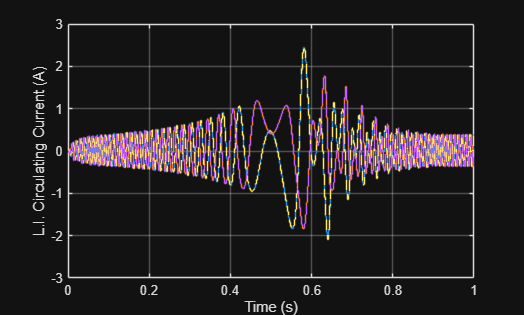

figure
stairs(Tsim, buffer.ie')
hold on
stairs(Tsim, buffer.ie_ref', '--')
hold off
xlabel('Time (s)')
ylabel('L.I. Circulating Current (A)')
grid on

## `vo`

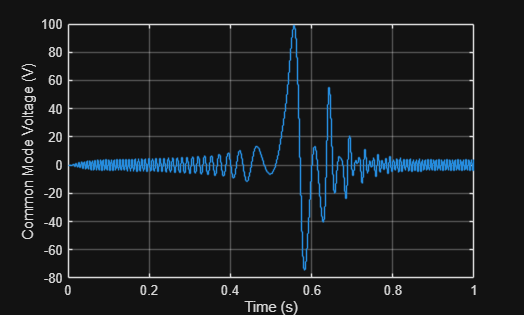

figure
stairs(Tsim, buffer.vo')
xlabel('Time (s)')
ylabel('Common Mode Voltage (V)')
grid on

## Exit Flags

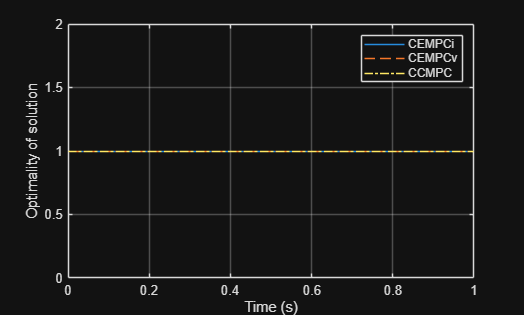

figure
stairs(Tsim, buffer.exitflag_CEMPCi', '-')
hold on
stairs(Tsim, buffer.exitflag_CEMPCv', '--')
stairs(Tsim, buffer.exitflag_CCMPC', '-.')
hold off
ylabel('Optimality of solution')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on

## Active Constraints

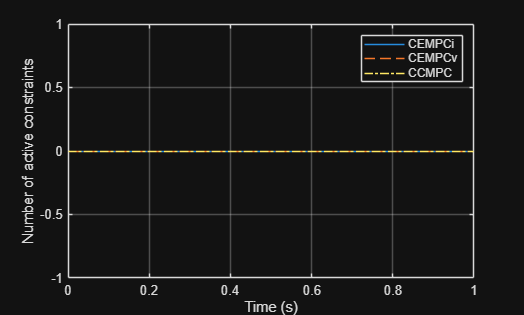

figure
stairs(Tsim, buffer.iA_CEMPCi', '-')
hold on
stairs(Tsim, buffer.iA_CEMPCv', '--')
stairs(Tsim, buffer.iA_CCMPC', '-.')
hold off
ylabel('Number of active constraints')
xlabel('Time (s)')
legend('CEMPCi', 'CEMPCv', 'CCMPC')
grid on

## Controller Execution Time

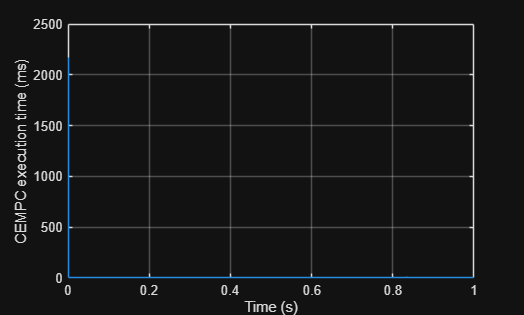

figure
stairs(Tsim, buffer.Tex_CEMPC'*1000)
ylabel('CEMPC execution time (ms)')
xlabel('Time (s)')
grid on

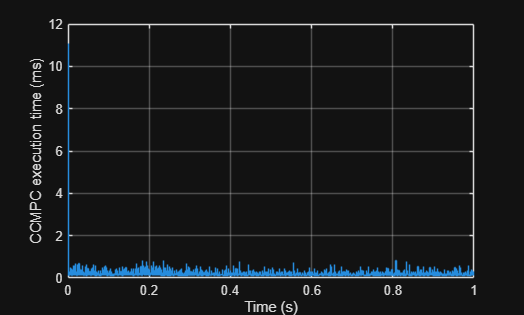


figure
stairs(Tsim, buffer.Tex_CCMPC'*1000)
ylabel('CCMPC execution time (ms)')
xlabel('Time (s)')
grid on